%% Leer datos
clear;
T = readtable('angulos_recortados\142ANGLES_recortado.csv');


%% Tiempo
t = T.Time;

% Angles 1
Ox1 = T.Angle1_o_0_X;
Oy1 = T.Angle1_o_0_Y;

Ax1 = T.Angle1_a_0_X;
Ay1 = T.Angle1_a_0_Y;

Bx1 = T.Angle1_b_0_X;
By1 = T.Angle1_b_0_Y;

% Angles 2
Ox2 = T.Angle2_o_0_X;
Oy2 = T.Angle2_o_0_Y;

Ax2 = T.Angle2_a_0_X;
Ay2 = T.Angle2_a_0_Y;

Bx2 = T.Angle2_b_0_X;
By2 = T.Angle2_b_0_Y;

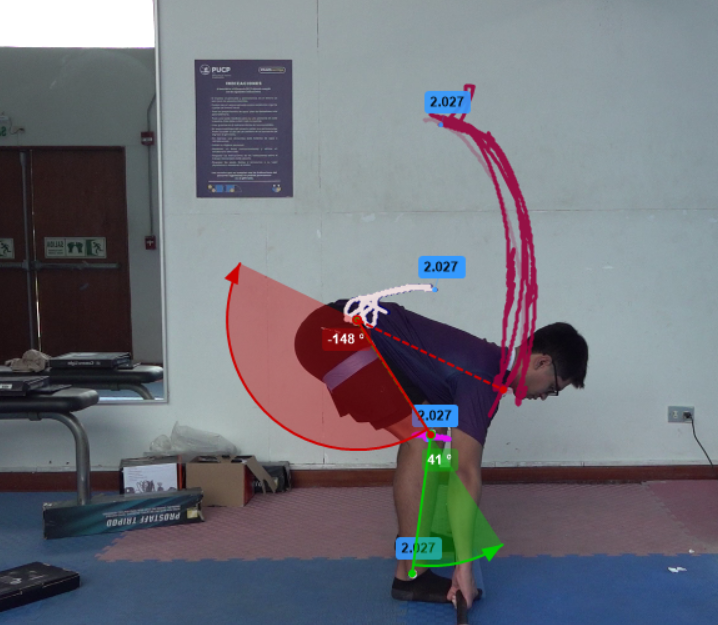

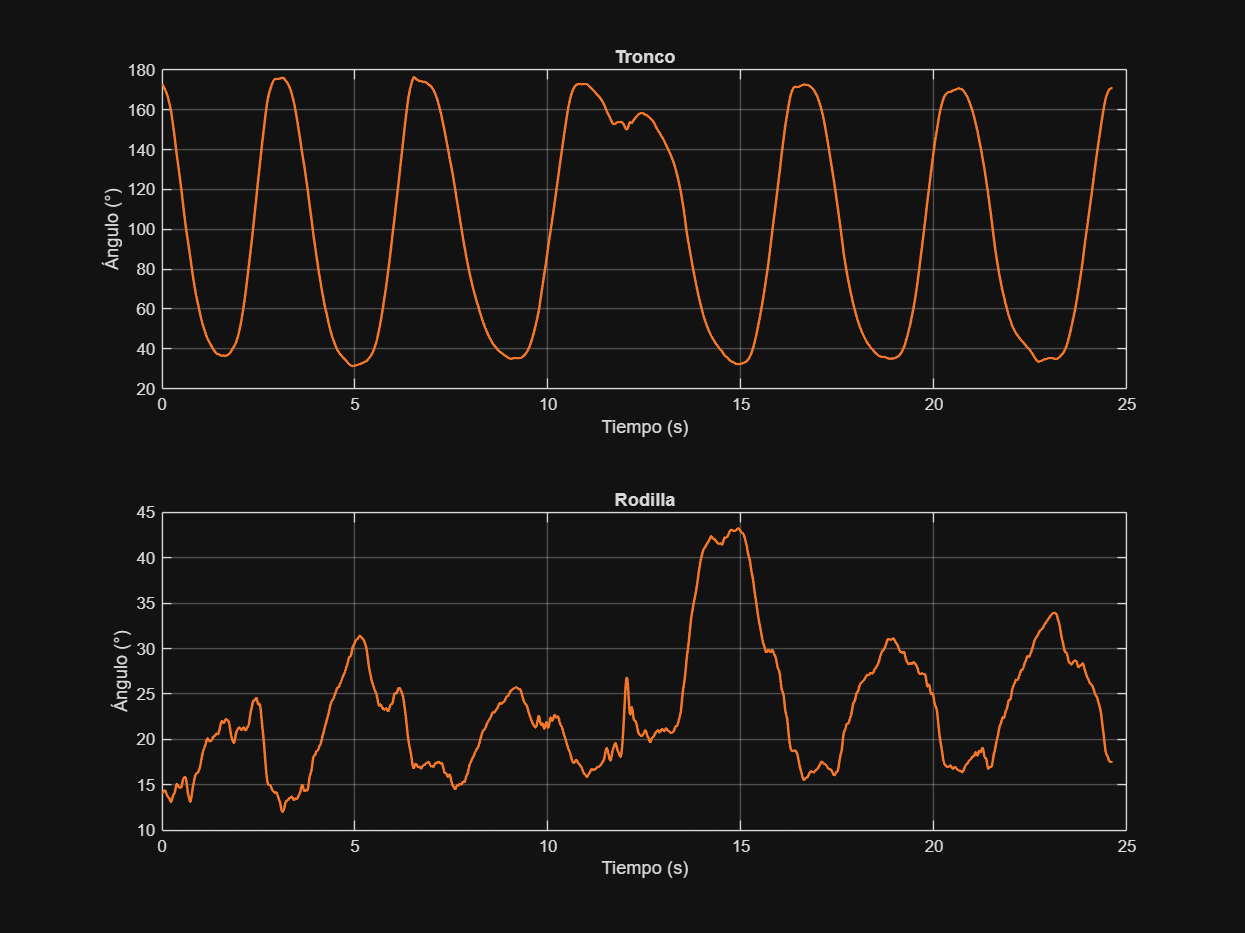

%% Ángulos

% Método actual (0-180°)
theta1 = calcAngles(Ox1, Oy1, Ax1, Ay1, Bx1, By1);
theta2 = calcAngles(Ox2, Oy2, Ax2, Ay2, Bx2, By2);

% Método 0-360°
theta1_360 = calcAngles360(Ox1, Oy1, Ax1, Ay1, Bx1, By1);
theta2_360 = calcAngles360(Ox2, Oy2, Ax2, Ay2, Bx2, By2);

% Ajuste Kinovea para rodilla
theta2 = 180 - theta2;
theta2_360 = 180 - theta2_360;

%% Suavizado

theta_f1 = smoothdata(theta1,'movmean',6);
theta_f2 = smoothdata(theta2,'movmean',6);

theta_f1_360 = smoothdata(theta1_360,'movmean',6);
theta_f2_360 = smoothdata(theta2_360,'movmean',6);

%% Comparación

figure(Position=[0,0,1200,900]);

subplot(2,1,1)
plot(t,theta_f1,'LineWidth',1.5)
hold on
plot(t,theta_f1_360,'LineWidth',1.5)
grid on
xlabel('Tiempo (s)')
ylabel('Ángulo (°)')
title('Tronco')

subplot(2,1,2)
plot(t,theta_f2,'LineWidth',1.5)
hold on
plot(t,theta_f2_360,'LineWidth',1.5)
grid on
xlabel('Tiempo (s)')
ylabel('Ángulo (°)')
title('Rodilla')

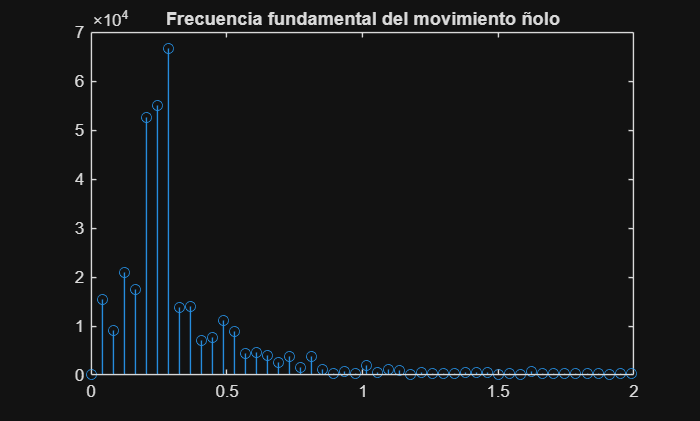


N  = length(theta_f1);
dt = t(2) - t(1);        % ≈ 0.0084 s
fs = 1 / dt;             % ≈ 119 Hz
f  = (0:N-1) * (fs/N);  % Vector de frecuencias en Hz
theta_centered = theta_f1 - mean(theta_f1);

Mag = abs(fft(theta_centered));
figure;
stem(f,Mag);title("Frecuencia fundamental del movimiento ñolo");xlim([0,2])

ROM_rodilla = [min(theta_f1), max(theta_f1)];
ROM_tronco  = [min(theta_f2), max(theta_f2)];

fprintf('El rango de mov del tronco es de %.2f° a %.2f°\n', ROM_tronco(1), ROM_tronco(2));

El rango de mov del tronco es de 12.03° a 43.24°


fprintf('El rango de mov de la rodilla es de %.2f° a %.2f°\n', ROM_rodilla(1), ROM_rodilla(2));

El rango de mov de la rodilla es de 31.33° a 176.32°



[valor_maximo, indice_maximo] = max(Mag);
f_del_mov = f(indice_maximo);
duracion_ciclo = 1/f_del_mov;

fprintf('La frecuencia principal del movimiento es: %.3f Hz\n', f_del_mov);

La frecuencia principal del movimiento es: 0.284 Hz


fprintf('La duracion del ciclo es: %.3f s\n', duracion_ciclo);

La duracion del ciclo es: 3.519 s


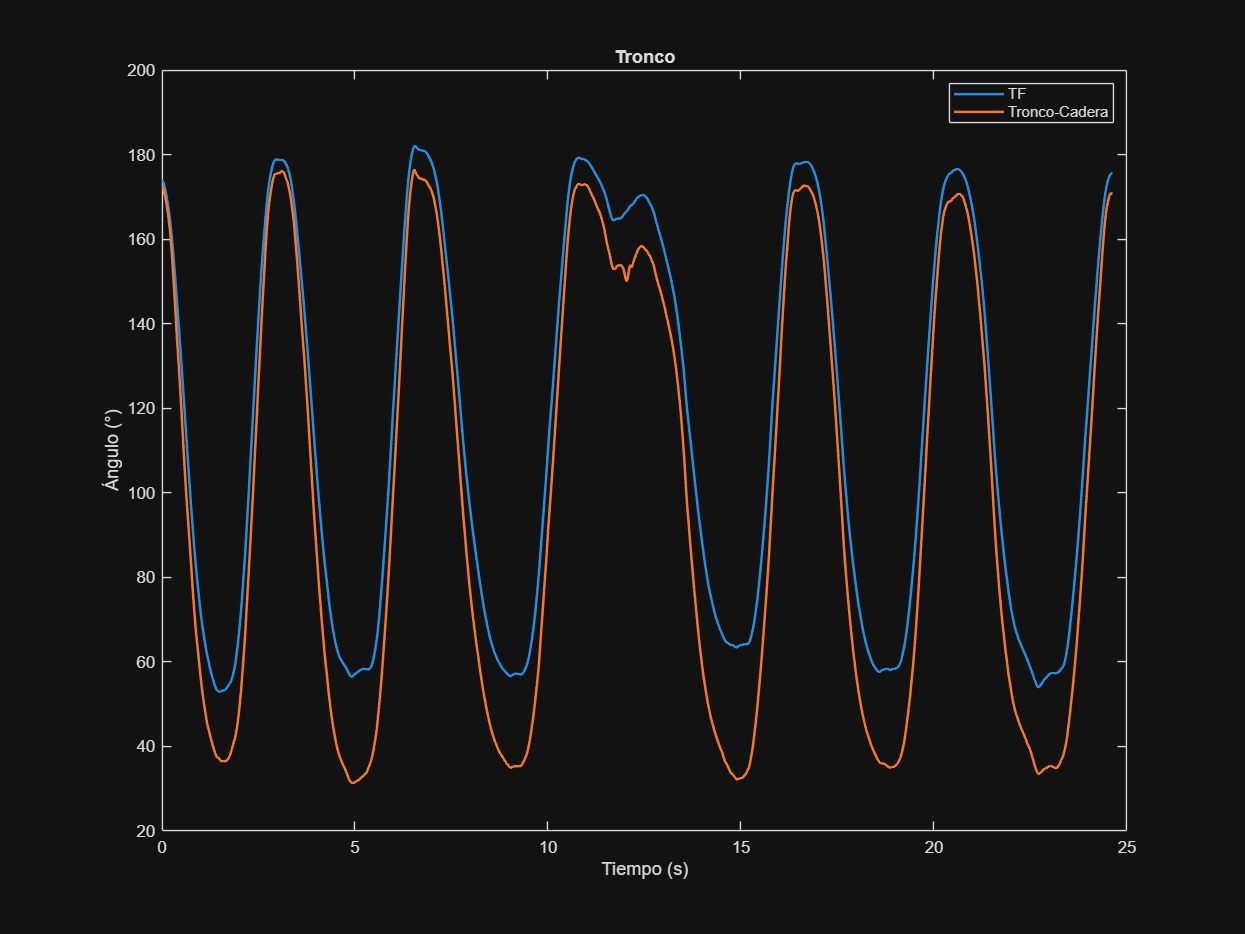


thetaT= calcAnglesT(Ox1, Oy1, Bx1, By1);
thetaTF = smoothdata(thetaT,'movmean',6);
thetaTF = 180-thetaTF;

figure(Position=[0,0,1200,900]);
plot(t,thetaTF,'LineWidth',1.5)
hold on
plot(t,theta_f1_360 ,'LineWidth',1.5)
hold on
xlabel('Tiempo (s)')
ylabel('Ángulo (°)')
title('Tronco');legend("TF","Tronco-Cadera")

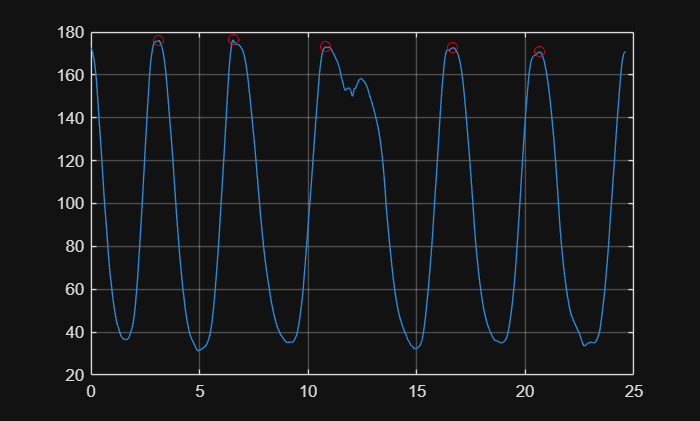

[pks,locs] = findpeaks(theta_f1_360,...
    'MinPeakDistance',100,...
    'MinPeakProminence',10);


figure;
plot(t,theta_f1_360)
hold on
plot(t(locs),theta_f1(locs),'ro')
grid on

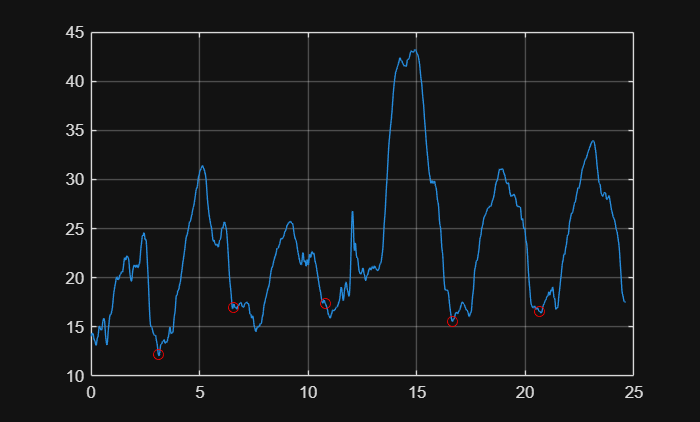

figure;
plot(t,theta_f2_360)
hold on
plot(t(locs),theta_f2(locs),'ro')
grid on

    
% FUNCIONES
function theta = calcAngles(Ox, Oy, Ax, Ay, Bx, By)
    %% Vectores OA y OB
    OAx = Ax - Ox;
    OAy = Ay - Oy;
    OBx = Bx - Ox;
    OBy = By - Oy;
    
    %% Ángulo original
    dotprod  = OAx.*OBx + OAy.*OBy;
    normOA   = sqrt(OAx.^2 + OAy.^2);
    normOB   = sqrt(OBx.^2 + OBy.^2);
    theta    = acosd(dotprod ./ (normOA .* normOB));

end

function theta = calcAngles360(Ox, Oy, Ax, Ay, Bx, By)

    OAx = Ax - Ox;
    OAy = Ay - Oy;

    OBx = Bx - Ox;
    OBy = By - Oy;

    dotprod = OAx.*OBx + OAy.*OBy;
    crossprod = OAx.*OBy - OAy.*OBx;

    theta = atan2d(crossprod, dotprod);

    theta(theta < 0) = theta(theta < 0) + 360;

end
function theta = calcAnglesT(Ox, Oy, Ax, Ay)

    OAx = Ax - Ox;
    OAy = Ay - Oy;
    
    theta = atan2d(OAx, OAy);
end